openExample('simulink_general/penddemoExample')

% cart --> (u[1]/m - g*sin(u[3])*cos(u[3]) + l*power(u[2],2)*sin(u[3]))/(Mcart/m + power(sin(u[3]),2))
% pend --> (-u[1]*cos(u[3])/m + (Mcart+m)*g*sin(u[3])/m - l*power(u[2],2)*sin(u[3])*cos(u[3]))/(l*(Mcart/m + power(sin(u[3]),2)))

% Initialize the Fuzzy Inference System with no rules
FIS = mamfis( ...
    'NumInputs', 1, ...
    'NumInputMFs', 2, ...
    'NumOutputs', 1, ...
    'NumOutputMFs', 2, ...
    'AddRule', 'none'...
    );

% Define inputs
FIS.Inputs(1).Name = 'Theta';
FIS.Inputs(1).Range = [-pi, pi];
FIS.Inputs(1).MembershipFunctions(1).Name = 'Negative';
FIS.Inputs(1).MembershipFunctions(1).Type = 'zmf'       % Z membership function

FIS =   mamfis with properties:

                       Name: "fis"
                  AndMethod: "min"
                   OrMethod: "max"
          ImplicationMethod: "min"
          AggregationMethod: "max"
      DefuzzificationMethod: "centroid"
                     Inputs: [1×1 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [0×0 fisrule]
    DisableStructuralChecks: 0

	See 'getTunableSettings' method for parameter optimization.


FIS.Inputs(1).MembershipFunctions(1).Parameters = [-0.5 0.5];
FIS.Inputs(1).MembershipFunctions(2).Name = 'Positive';
FIS.Inputs(1).MembershipFunctions(2).Type = 'smf'

FIS =   mamfis with properties:

                       Name: "fis"
                  AndMethod: "min"
                   OrMethod: "max"
          ImplicationMethod: "min"
          AggregationMethod: "max"
      DefuzzificationMethod: "centroid"
                     Inputs: [1×1 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [0×0 fisrule]
    DisableStructuralChecks: 0

	See 'getTunableSettings' method for parameter optimization.


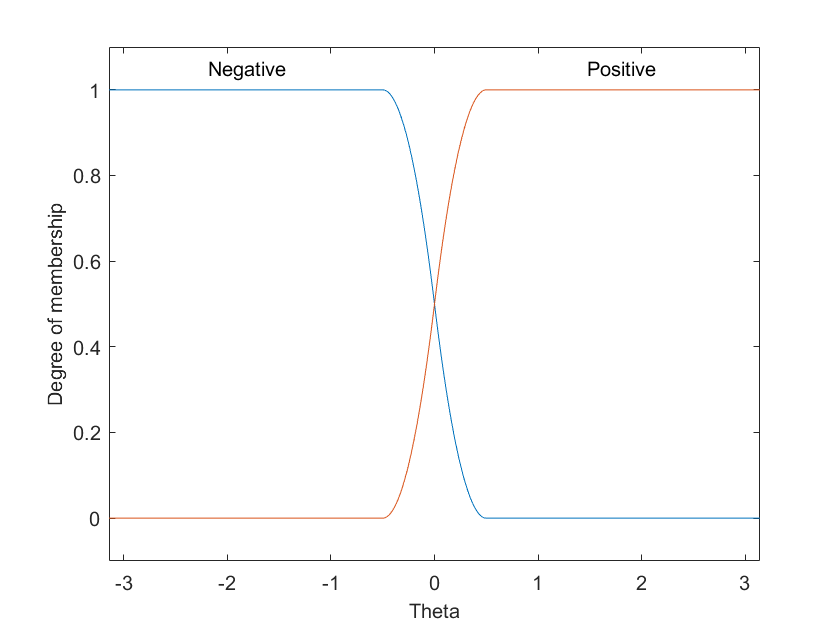

FIS.Inputs(1).MembershipFunctions(2).Parameters = [-0.5 0.5];

plotmf(FIS, 'input', 1, 1000);

% Define outputs
FIS.Outputs(1).Name = 'Force';
FIS.Outputs(1).Range = [-20, 20];
FIS.Outputs(1).MembershipFunctions(1).Name = 'NM';      % Negative Medium
FIS.Outputs(1).MembershipFunctions(1).Type = 'gbellmf'  % Generalized Bell

FIS =   mamfis with properties:

                       Name: "fis"
                  AndMethod: "min"
                   OrMethod: "max"
          ImplicationMethod: "min"
          AggregationMethod: "max"
      DefuzzificationMethod: "centroid"
                     Inputs: [1×1 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [0×0 fisrule]
    DisableStructuralChecks: 0

	See 'getTunableSettings' method for parameter optimization.


FIS.Outputs(1).MembershipFunctions(1).Parameters = [5, 2, -12];
FIS.Outputs(1).MembershipFunctions(2).Name = 'PM';      % Positive Medium
FIS.Outputs(1).MembershipFunctions(2).Type = 'gbellmf'  % Generalized Bell

FIS =   mamfis with properties:

                       Name: "fis"
                  AndMethod: "min"
                   OrMethod: "max"
          ImplicationMethod: "min"
          AggregationMethod: "max"
      DefuzzificationMethod: "centroid"
                     Inputs: [1×1 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [0×0 fisrule]
    DisableStructuralChecks: 0

	See 'getTunableSettings' method for parameter optimization.


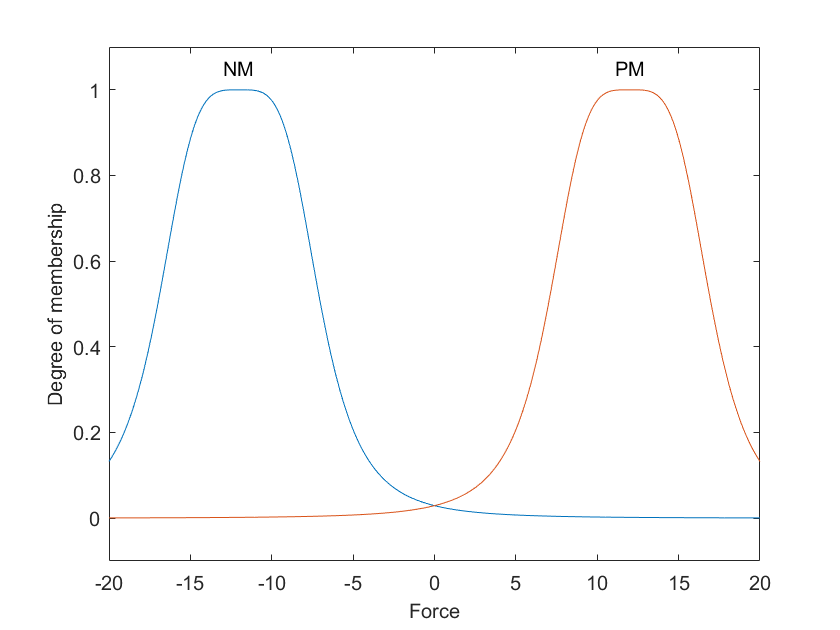

FIS.Outputs(1).MembershipFunctions(2).Parameters = [5, 2, 12];

plotmf(FIS, 'output', 1, 1000);

% Define rules
rules = [
    "If Theta is Negative then Force is NM";
    "If Theta is Positive then Force is PM"
    ];

FIS = addRule(FIS, rules);